clc; close all;

**Giordano Dylan - Martelet Curtis                            L3 EEA_Gr TP1**

# Rapport TDP5: Hacheur 4 quadrants

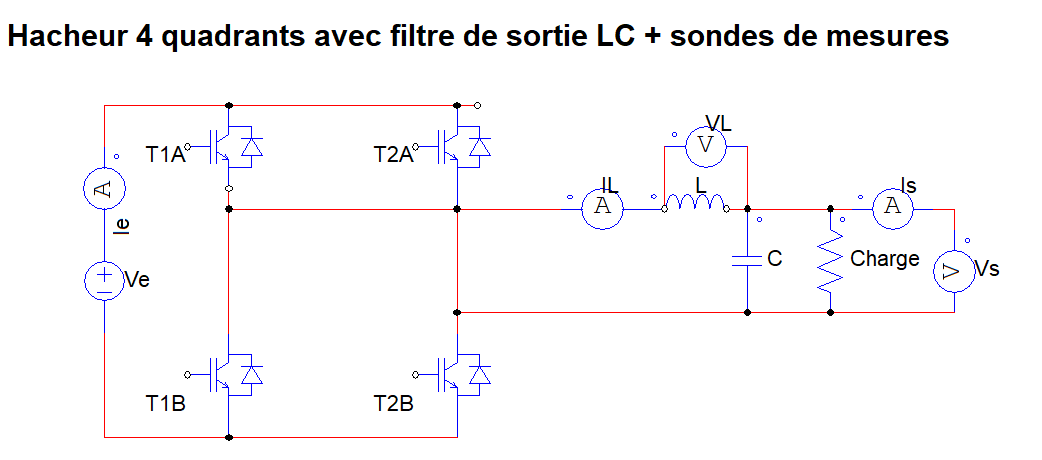

Afin d'avoir une puissance de sortie Ps de 180W, nous devons régler la charge R a 20$\Omega$.

R=$\frac{{\textrm{Vs}}^2 }{\textrm{Ps}}$=$\frac{{60}^2 }{180}$=20$\Omega$

## 3. Hacheur 4 quadrants avec filtre de sortie LC.

### 3.2) Mesures de valeurs moyennes

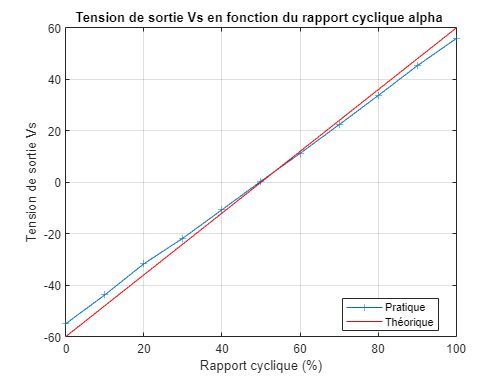

%%On prend la charge R=20 ohms pour Ps=180W
Ue=60;

alpha=[0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1];

Vs=[-55 -43.8 -31.7 -21.75 -10.7 0.43 11.22 22.4 33.7 45.3 55.9];
Ie=[2.78   1.77  0.98  0.48   0.17  0.07 0.18  0.49 1.03 1.82 2.78];
Is=[-2.76   -2.19 -1.6  -1.07  -0.53 0.02 0.55 1.1  1.65 2.22 2.76];

Vsth=(2.*alpha-1)*Ue;

plot(alpha*100,Vs,'+-',alpha*100,Vsth,'r');
title("Tension de sortie Vs en fonction du rapport cyclique alpha ");
xlabel("Rapport cyclique (%)"); ylabel("Tension de sortie Vs");
grid on;
legend('Pratique','Théorique','Location','best');

On peut observer que l'allure de la courbe pratique est similaire à la courbe théorique.

Cette courbe est linéaire symétrique au point 0 (quand α=50%) puisque $V_S =\left(2\alpha -1\right)\times V_e$.

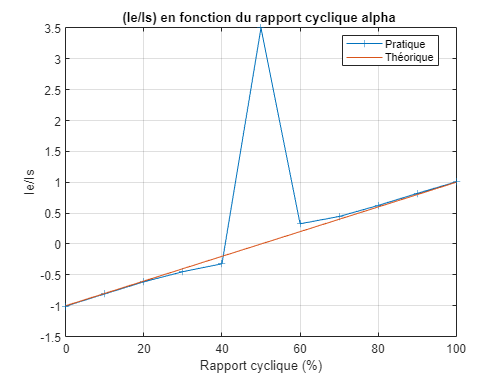

plot(alpha*100,Ie./Is,'+-',alpha*100,(2.*alpha-1));
title("(Ie/Is) en fonction du rapport cyclique alpha ");
xlabel("Rapport cyclique (%)"); ylabel("Ie/Is");
grid on;
legend('Pratique','Théorique','Location','best');

Sur cette courbe, on observe un pic à α=50%: pour rappel, sur la précedente courbe, on mesure Vs environ 0V pour ce rapport cyclique et puisque $I_S =\frac{V_S }{R}$, alors on trouve un Is proche de 0. Théoriquement, nous devrions avoir un rapport nul, mais les transistors utilisés pour le bloc hacheur/onduleur consomment en permanence environ 0.6A. Le rapport Ie/Is est donc très grand pour ce rapport cyclique.

### 3.3) Mesure de l'ondulation de courant dans l'inductance & de l'ondulation de tension de sortie

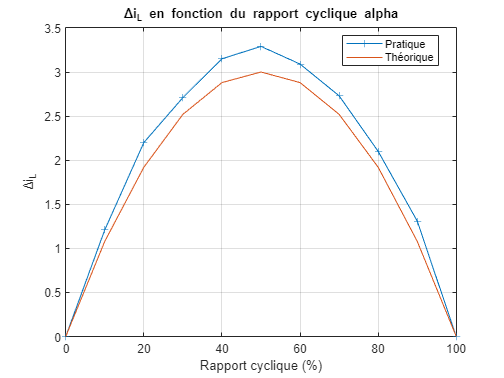

delta_iL=[0 1.21 2.2 2.71 3.15 3.29 3.09 2.73 2.1 1.31 0];

L=1e-3; Fdec=10e3;
delta_iL_th=(2.*alpha.*Ue.*(1-alpha))./(L.*Fdec);
    
plot(alpha*100,delta_iL,'+-',alpha*100,delta_iL_th);
title("Δi_L en fonction du rapport cyclique alpha");
xlabel("Rapport cyclique (%)"); ylabel("Δi_L");
grid on;
legend('Pratique','Théorique','Location','best');

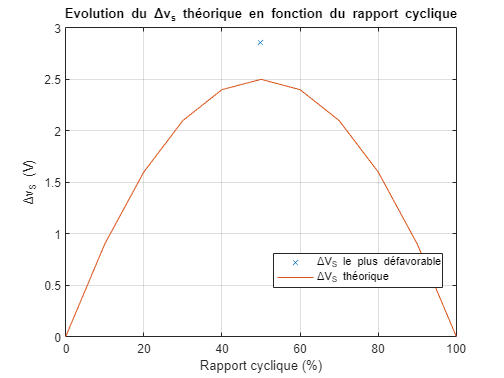

dVs = (2.*alpha*60.*(1-alpha))/(8*1e-3*15e-6*10e3^2);

plot(50,2.86,'X',alpha*100,dVs);
title("Evolution du Δv_s théorique en fonction du rapport cyclique");
xlabel("Rapport cyclique (%)"); ylabel("Δv_S (V)");
legend("ΔV_S le plus défavorable","ΔV_S théorique","location","best")
ylim([0 3])
grid on;

Dans le cas le plus défavorable (à α=50%), ΔVs théorique est égal à 2.5V. En pratique, nous mesurons 2.86V.

#### Pour α=30%:

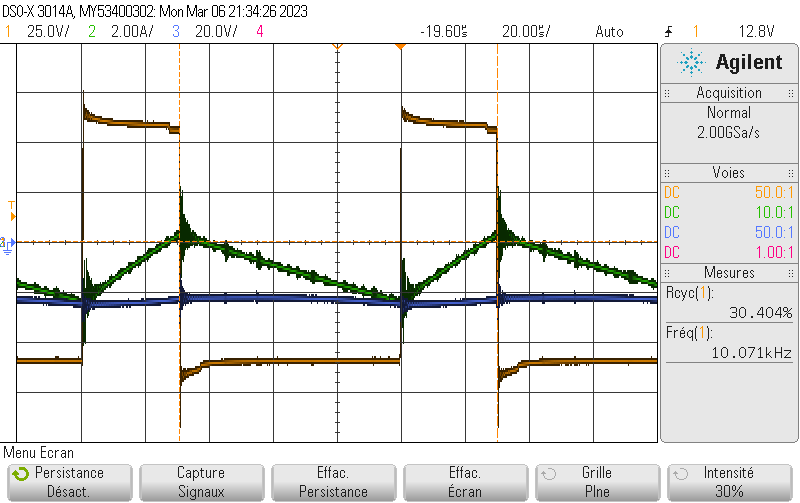

On peut voir que la valeur moyenne de la tension 

#### Pour α=80%: 

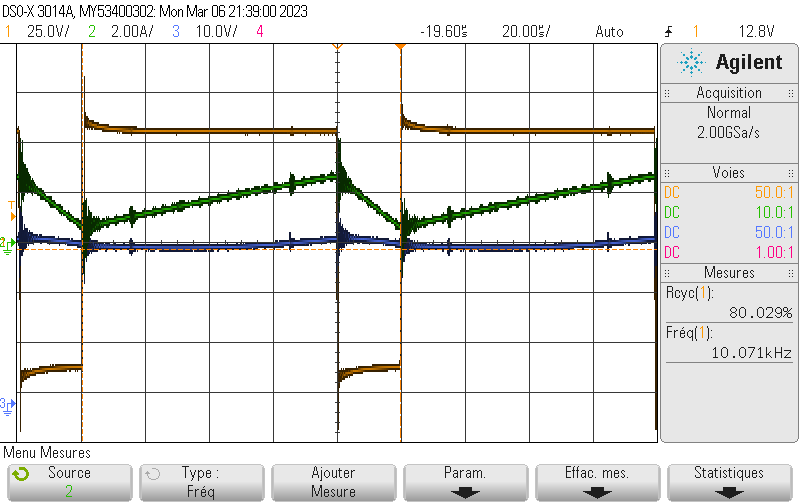

Courbe bleu=vS(t); Courbe jaune=v(t); Courbe verte=iL(t)

## 4. Alimentation en vitesse variable d'une machine à courant continue par un hacheur 4 quadrants.

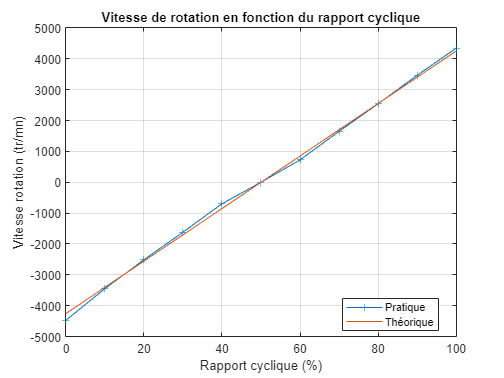

alpha=[0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1];
N=[-4476 -3450 -2513 -1618 -697 0 726 1650 2543 3468 4347];
us=[-57.5 -45.8 -33.6 -22.71 -10.53 0 0.223 23.1 35.2 47.4 59];

k = 65.6e-3;R=0.552;
N_theorique = (Vsth-R*Is)/(2*k)*9.5492965855137;

plot(alpha*100,N,'+-',alpha*100,N_theorique);
title("Vitesse de rotation en fonction du rapport cyclique");
xlabel("Rapport cyclique (%)"); ylabel("Vitesse rotation (tr/mn)");
legend("Pratique","Théorique","Location","best")
grid on;

On peut observer que la vitesse de rotation du moteur est linéaire en fonction du rapport cyclique.

Le sens de rotation du moteur est lié à α:

- de 0 à 40%, le moteur tourne dans un sens sens (que l'on va appeler "sens inverse").

- à 50%, le moteur est arreté. 

- de 60 à 100%, le moteur tourne dans l'autre sens.

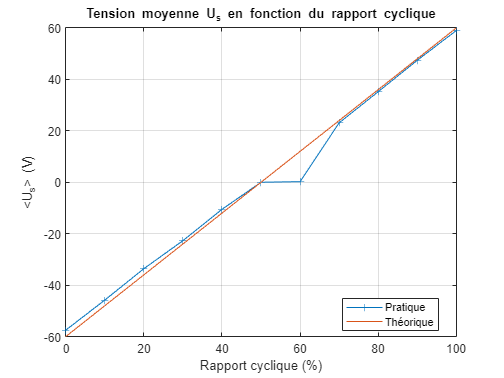

plot(alpha*100,us,'+-',alpha*100,Vsth);
grid on
title("Tension moyenne U_s en fonction du rapport cyclique");
xlabel("Rapport cyclique (%)"); ylabel("<U_s> (V)");
legend("Pratique","Théorique","Location","best")
grid on;

On peut observer que la variation de la tension moyenne est linéaire en fonction du rapport cyclique. Cependant, la tension Us est égale à 0 entre α=50 et 60%: comme vu lors des expérimentations sur le moteur continue (S5), ce dernier ne démarre pas directement 